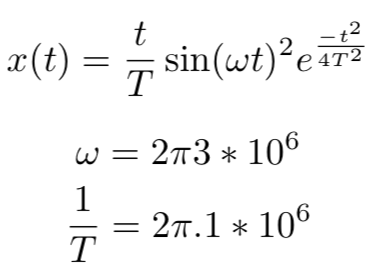

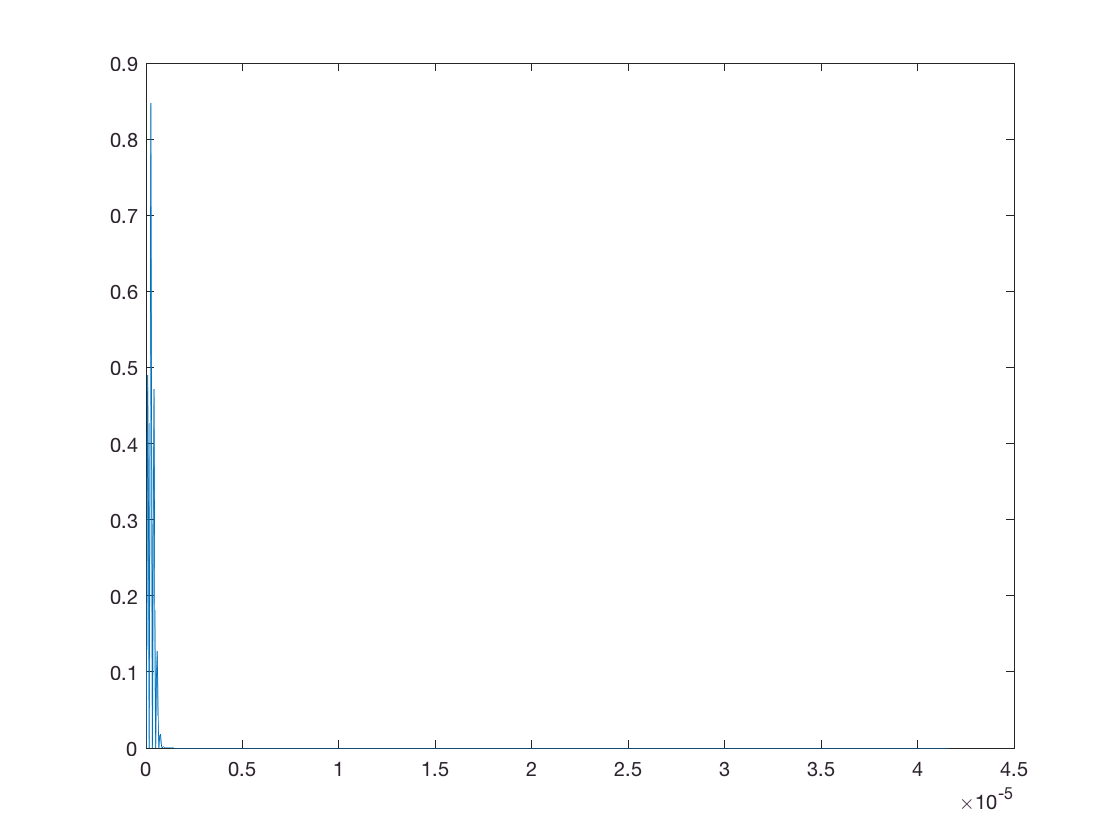

T=1/(2*pi*10^6);
w=2*pi*3*10^6;
%%%%a%%%
Fs=24*10^6;
Ts=1/Fs;
L = 1000;              % Length of signal
t = (0:L-1)*Ts;        % Time vector
x=(t/T).*((sin(w.*t)).^2).*exp(-((t./(2*T)).^2));
plot(t,x)

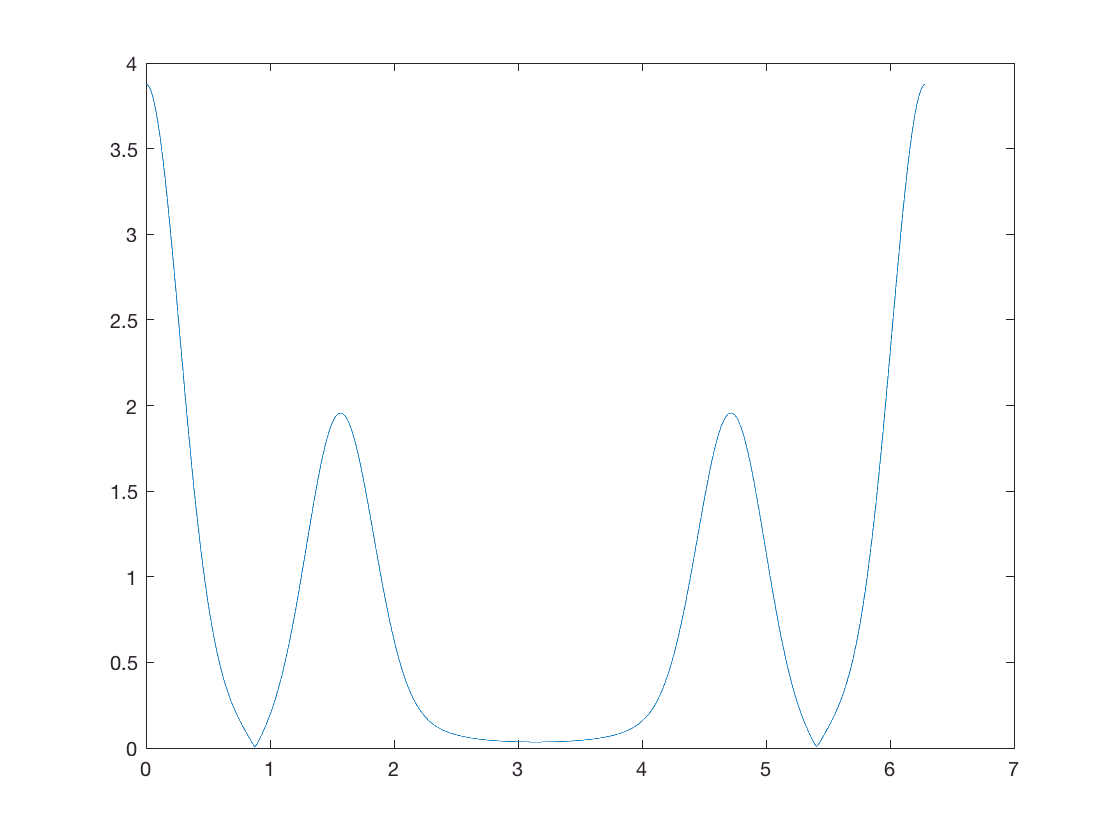



X=fft(x,2*length(x));

plot(linspace(0,2*pi,length(X)),abs(X))

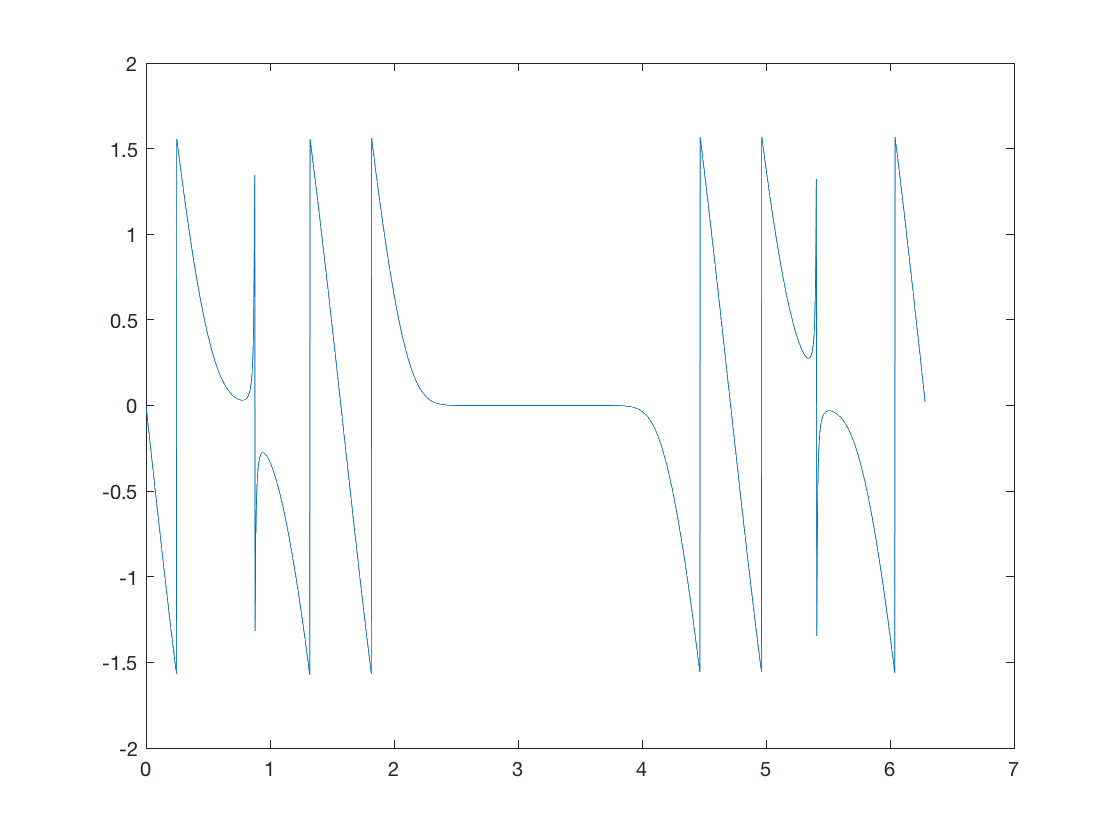

phi=imag(X)./real(X);
plot(linspace(0,2*pi,length(X)),atan(phi))

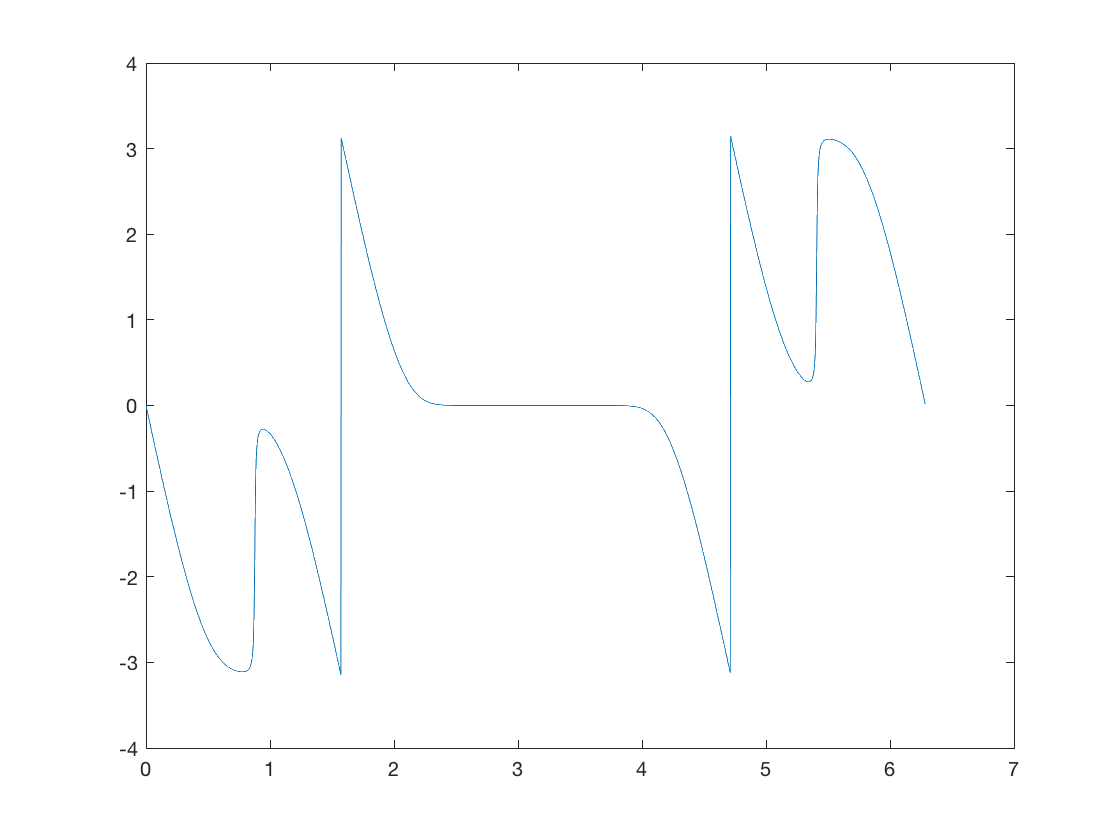

quad4=atan2(imag(X),real(X));
plot(linspace(0,2*pi,length(X)),quad4)

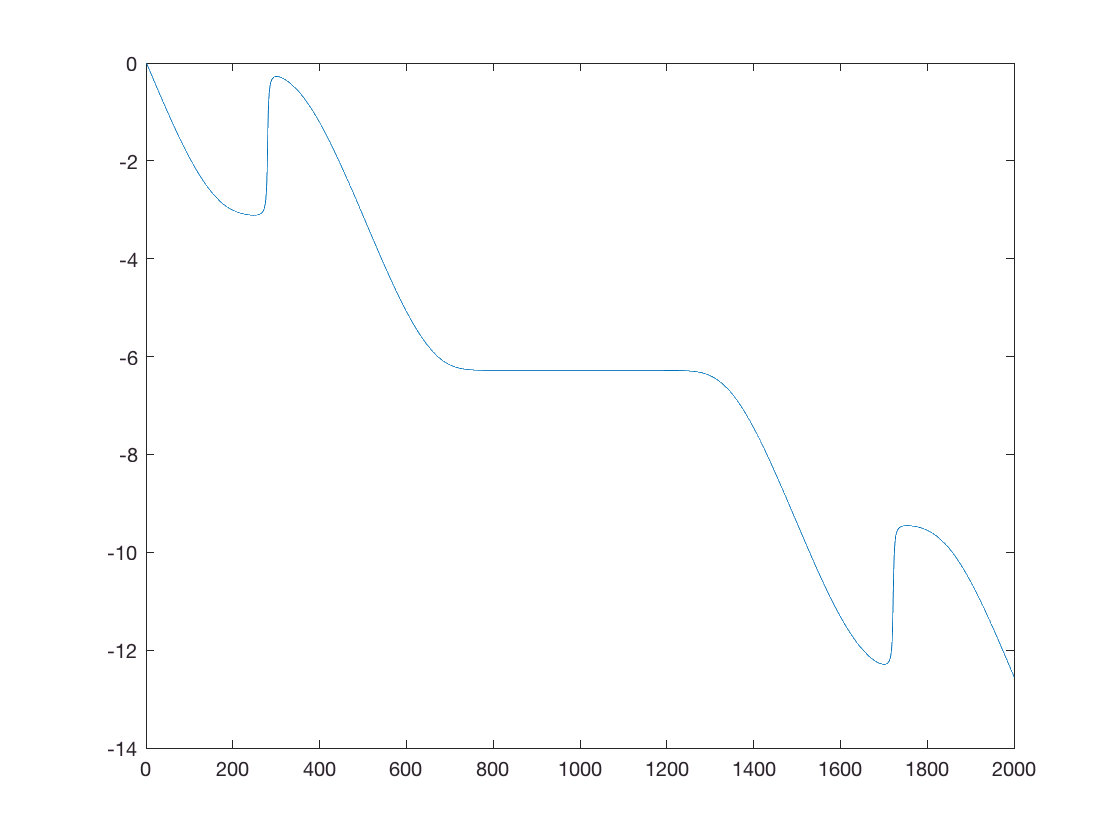

pq4=unwrap(quad4);
plot(pq4)